addpath('./functions');
addpath('./data');

[XTrain, YTrain, XTest, YTest] = load_data('data');

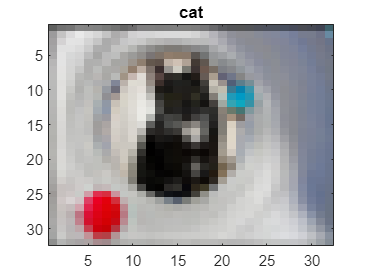

labels_names = ["Airplane", ...
                "Automobile", ...
                "Bird", ...
                "Cat", ...
                "Deer", ...
                "Dog", ...
                "Frog", ...
                "Horse", ...
                "Ship", ...
                "Truck", ...
                ];

labels_numbers = ["0", ...
                  "1", ...
                  "2", ...
                  "3", ...
                  "4", ...
                  "5", ...
                  "6", ...
                  "7", ...
                  "8", ...
                  "9", ...
                  ];

label2name = dictionary(labels_numbers, labels_names);
idx = randi(size(XTrain,4));

imagesc(XTrain(:,:,:,idx))
title(YTrain(idx))

% size(permutedImageData)
% test_size = 0.2
% % normalizedData = normalize(permutedImageData);
% [X_train, X_val, Y_train, Y_val] = train_test_split(permutedImageData, categoricalLabels, test_size);

% layers = basic_cnn_classifier()
% options = trainingOptions('sgdm', "ExecutionEnvironment","gpu",Plots="training-progress", MiniBatchSize=64, InitialLearnRate=0.001, MaxEpochs=10);
% net = trainNetwork(permutedImageData,categoricalLabels, layers, options);

% preds = net.classify(testData);
% tp = nnz(preds == testLabels);
% accuracy = tp / length(testLabels);
% disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

% layers = improved_cnn_classifier();
% options = trainingOptions('sgdm', "ExecutionEnvironment","gpu",Shuffle="every-epoch",Plots="training-progress", MiniBatchSize=64, InitialLearnRate=0.0001, MaxEpochs=30);
% net = trainNetwork(permutedImageData,categoricalLabels, layers, options);

% preds = net.classify(testData);
% tp = nnz(preds == testLabels);
% accuracy = tp / length(testLabels);
% disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

layers = basic_cnn_classifier_v2();

opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.002, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'ExecutionEnvironment','gpu');

basic_net = trainNetwork(XTrain, YTrain, layers, opts);

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       10.16% |       2.3139 |          0.0020 |
|       1 |          50 |       00:00:01 |       13.28% |       2.3054 |          0.0020 |
|       1 |         100 |       00:00:03 |       12.50% |       2.2905 |          0.0020 |
|       1 |         150 |       00:00:05 |       24.22% |       2.1529 |          0.0020 |
|       1 |         200 |       00:00:07 |       23.44% |       2.0957 |          0.0020 |
|       1 |         250 |       00:00:12 |       27.34% |       2.0539 |          0.0020 |
|       1 |         300 |       00:00:20 |       17

preds = basic_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 51.99%


layers = improved_cnn_classifier_v2();

opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.0002, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 8, ...
    'L2Regularization', 0.004, ...
    'MaxEpochs', 15, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'ExecutionEnvironment','gpu');

improved_net = trainNetwork(XTrain, YTrain, layers, opts);

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        8.59% |       2.3036 |          0.0002 |
|       1 |          50 |       00:00:08 |       17.97% |       2.2345 |          0.0002 |
|       1 |         100 |       00:00:17 |       23.44% |       2.1350 |          0.0002 |
|       1 |         150 |       00:00:24 |       29.69% |       1.9325 |          0.0002 |
|       1 |         200 |       00:00:32 |       29.69% |       1.9135 |          0.0002 |
|       1 |         250 |       00:00:39 |       35.16% |       1.8237 |          0.0002 |
|       1 |         300 |       00:00:47 |       41

preds = improved_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 62.45%
